# DL draft

(Section 4)

github@hnxj; github@dynasim

## 0. Initialization

clear;close all;clc;
PathToDynaSim = '/Users/hamednejat/Works/Research/Computational/DynaSim'; % Change it based on your local path for dynasim 
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

## 1.Neural circuit structure in Dynasim

PINH: Pyramidal-INterneuron Harmony circuit.

study_dir = 'dlModels/PINO1';

eqns={
  'dV/dt=@current+noise*randn(1,N_pop); noise=0; V(0) = -70 + 7*rand(1,N_pop);'
};

% Control current drive for direct stimulation purposes

nES = 75;
nIF = 15;
nIS = 10;

gBase = 0.1;
gGABAslow = gBase / nIS; % Receptor conductances
gGABAfast = gBase / nIF;
gAMPA = gBase / nES;

tauGABAslow = 50 + randn(1); % Receptor synaptic time constants; SST->~10Hz ~(1/2t = 1/100)
tauGABAfast = 5 + randn(1); % PV->~100Hz (1/10)
tauAMPA = 15 + randn(1); % PY->~33.3Hz (1/30)

eNoise = 20; % Baseline noise drive max amplitude
fNoise = 20;
sNoise = 20;

cCoeff = 2; % 

kEE = ones(nES, nES) / cCoeff;
kEIf = ones(nES, nIF) / cCoeff;
kEIs = ones(nES, nIS) / cCoeff;

kIfE = ones(nIF, nES) / cCoeff;
kIfIf = ones(nIF, nIF) / cCoeff;
kIfIs = ones(nIF, nIS) / cCoeff;

kIsE = ones(nIS, nES) / cCoeff;
kIsIf = ones(nIS, nIF) / cCoeff;
kIsIs = ones(nIS, nIS) / cCoeff;

s=[];
s.populations(1).name='ES';
s.populations(1).size=nES;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'gNa',120,'gK',36,'noise',eNoise};

s.populations(2).name='INfast';
s.populations(2).size=nIF;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'gNa',120,'gK',36,'noise',fNoise};

s.populations(3).name='INslow';
s.populations(3).size=nIS;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK'};
s.populations(3).parameters={'gNa',120,'gK',36,'noise',sNoise};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfE};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEIf};

s.connections(3).direction='INslow->ES';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsE};

s.connections(4).direction='ES->INslow';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEIs};

s.connections(5).direction='INslow->INfast';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsIf};

s.connections(6).direction='INslow->INslow';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIsIs};

s.connections(7).direction='INfast->INslow';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfIs};

s.connections(8).direction='INfast->INfast';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIfIf};

s.connections(9).direction='ES->ES';
s.connections(9).mechanism_list={'iAMPA'};
s.connections(9).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEE};

RunDuration = 1000; % In ms (miliseconds)
vary = {};

data = dsSimulate(s, 'tspan', [0 RunDuration], 'downsample_factor', 10, ...
                     'solver', 'euler', 'dt', .01, ...
                     'compile_flag', 0, 'parallel_flag', 1, ...
                     'vary', vary, 'verbose_flag', 1);


PREPARING STUDY:
Creating study directory: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/study_20240312111530
Creating data directory: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/study_20240312111530/data
Creating results directory: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/study_20240312111530/results
saving study file: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/study_20240312111530/studyinfo.mat

PREPARING SOLVER:
Creating solver directory /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/study_20240312111530/solve/sim1
Changing directory to /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/study_20240312111530/solve/sim1
Saving params.mat
Creating solver file: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/study_20240312111530/solve/sim1/solve_ode_20240312111531_681.m
Changing directory back to /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim

SIMULAT

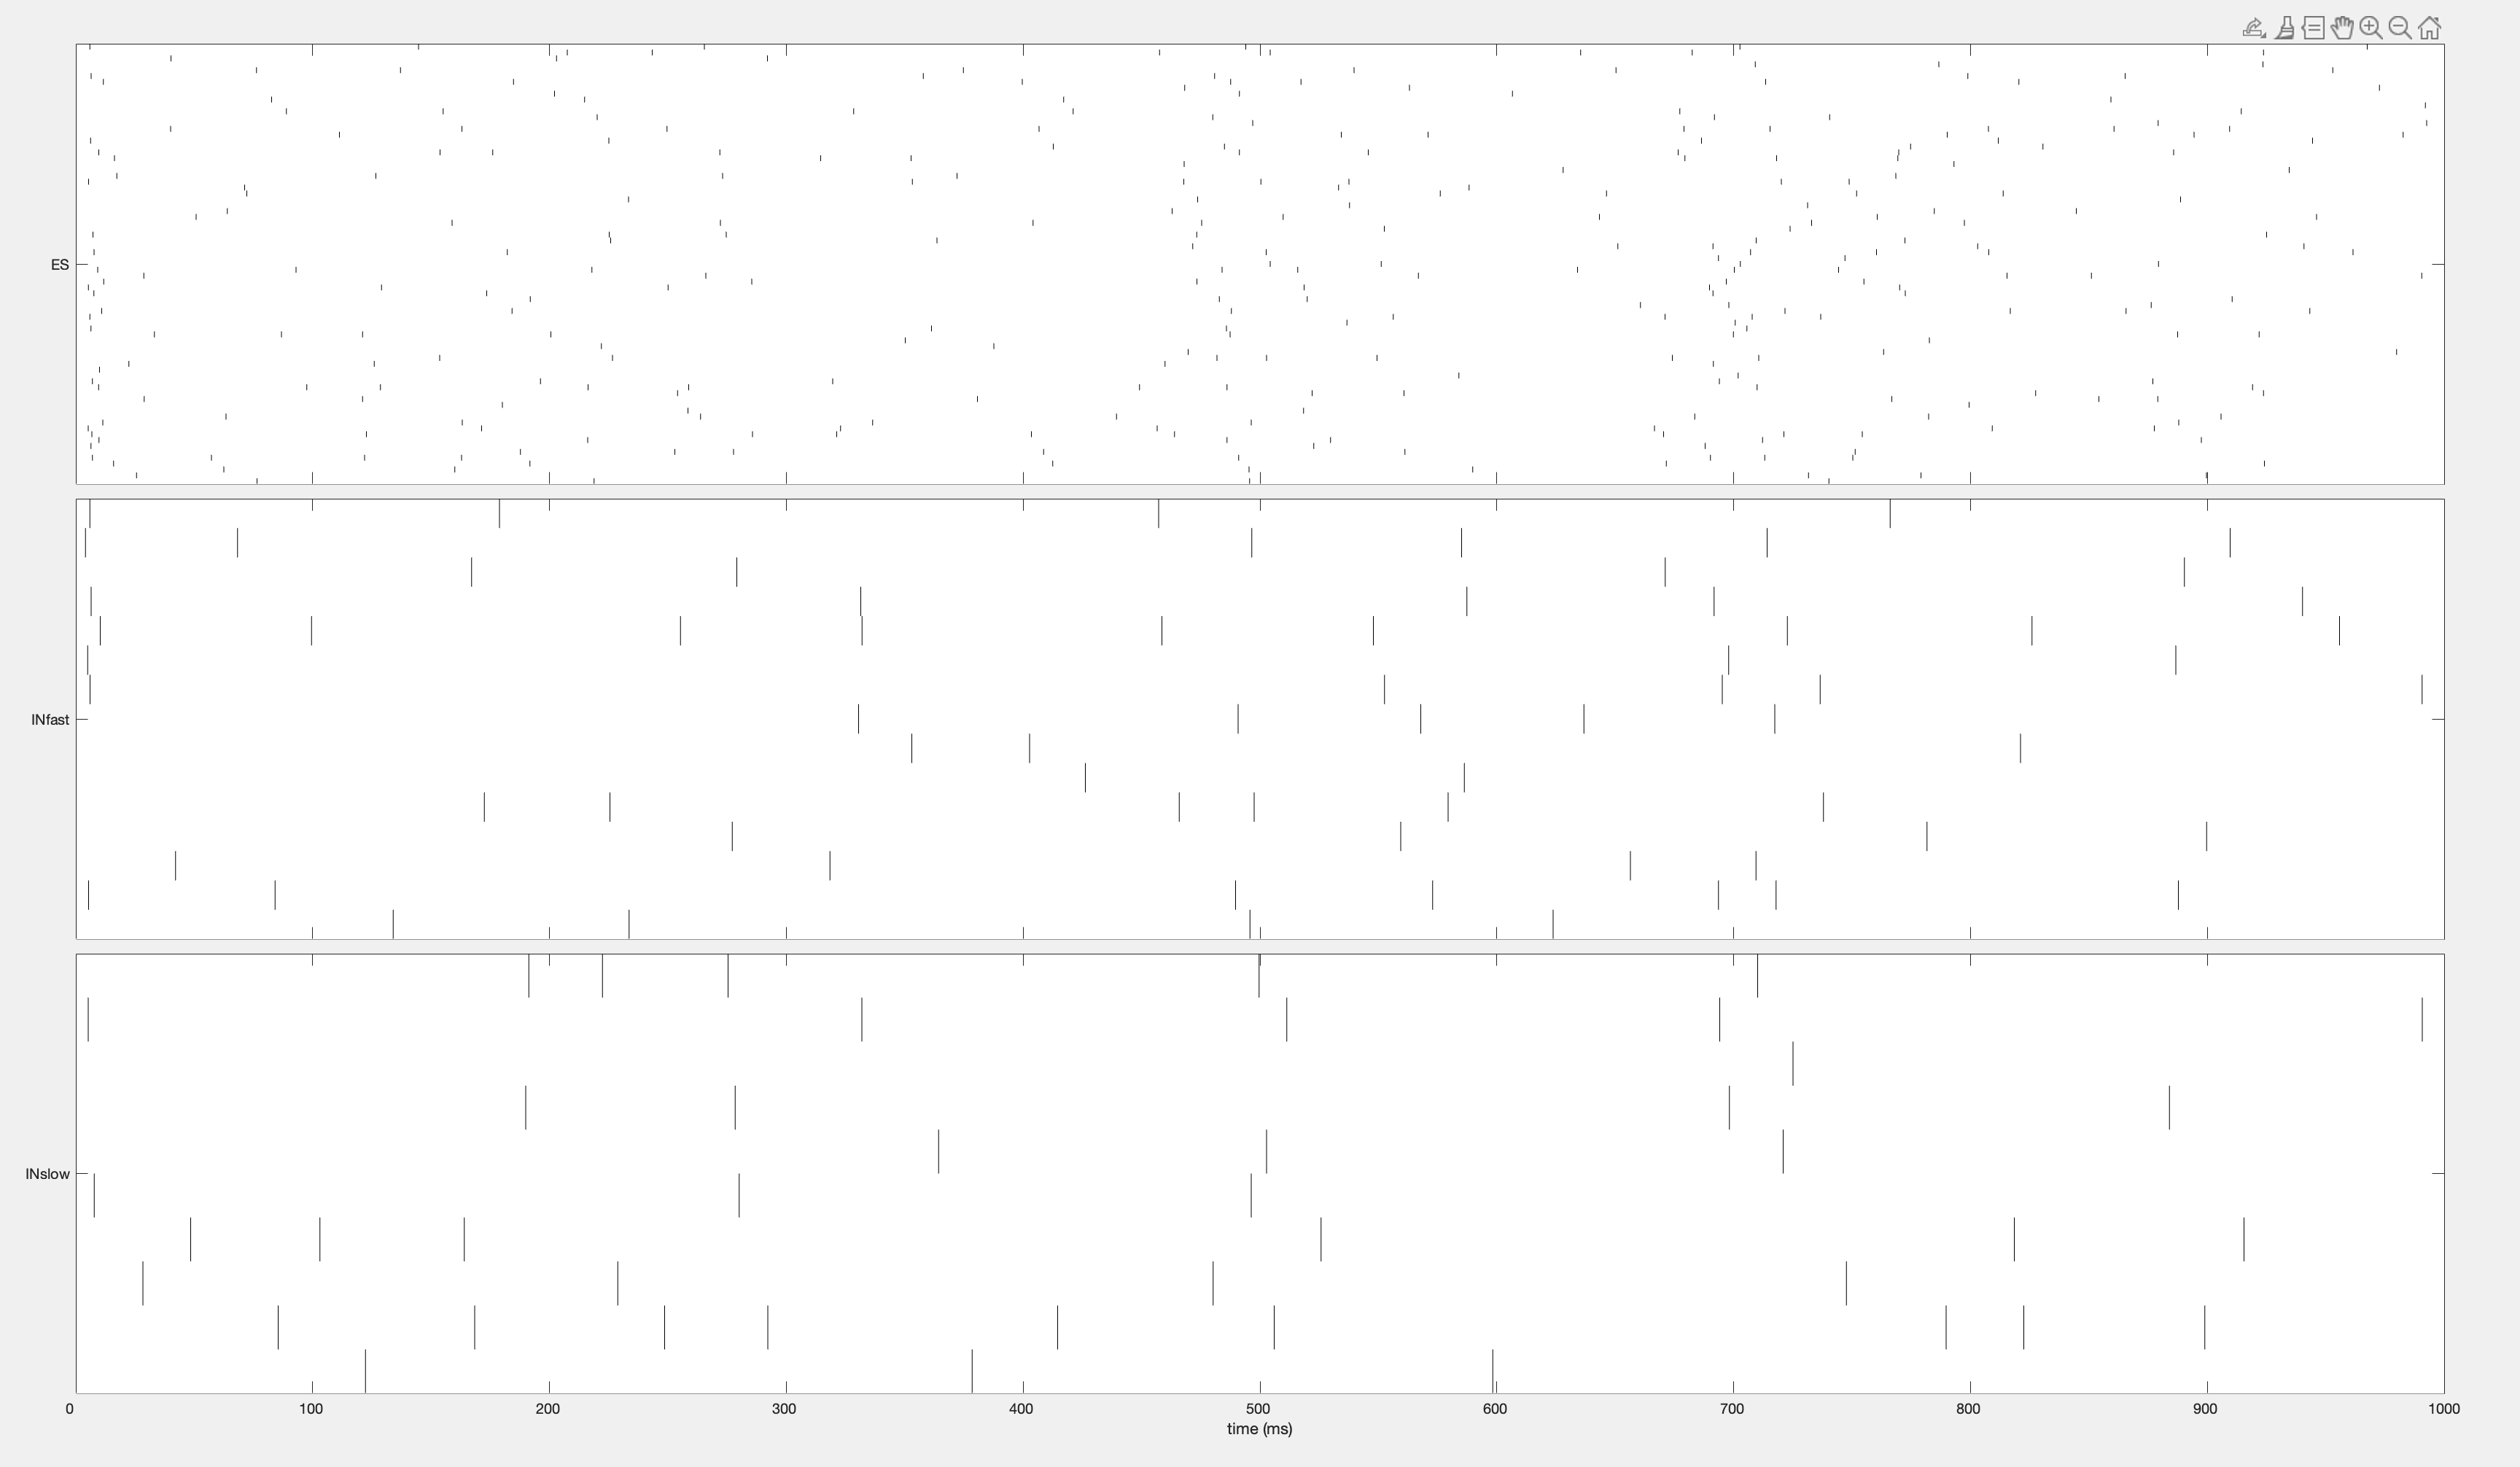

dsPlot(data, 'plot_type','raster');

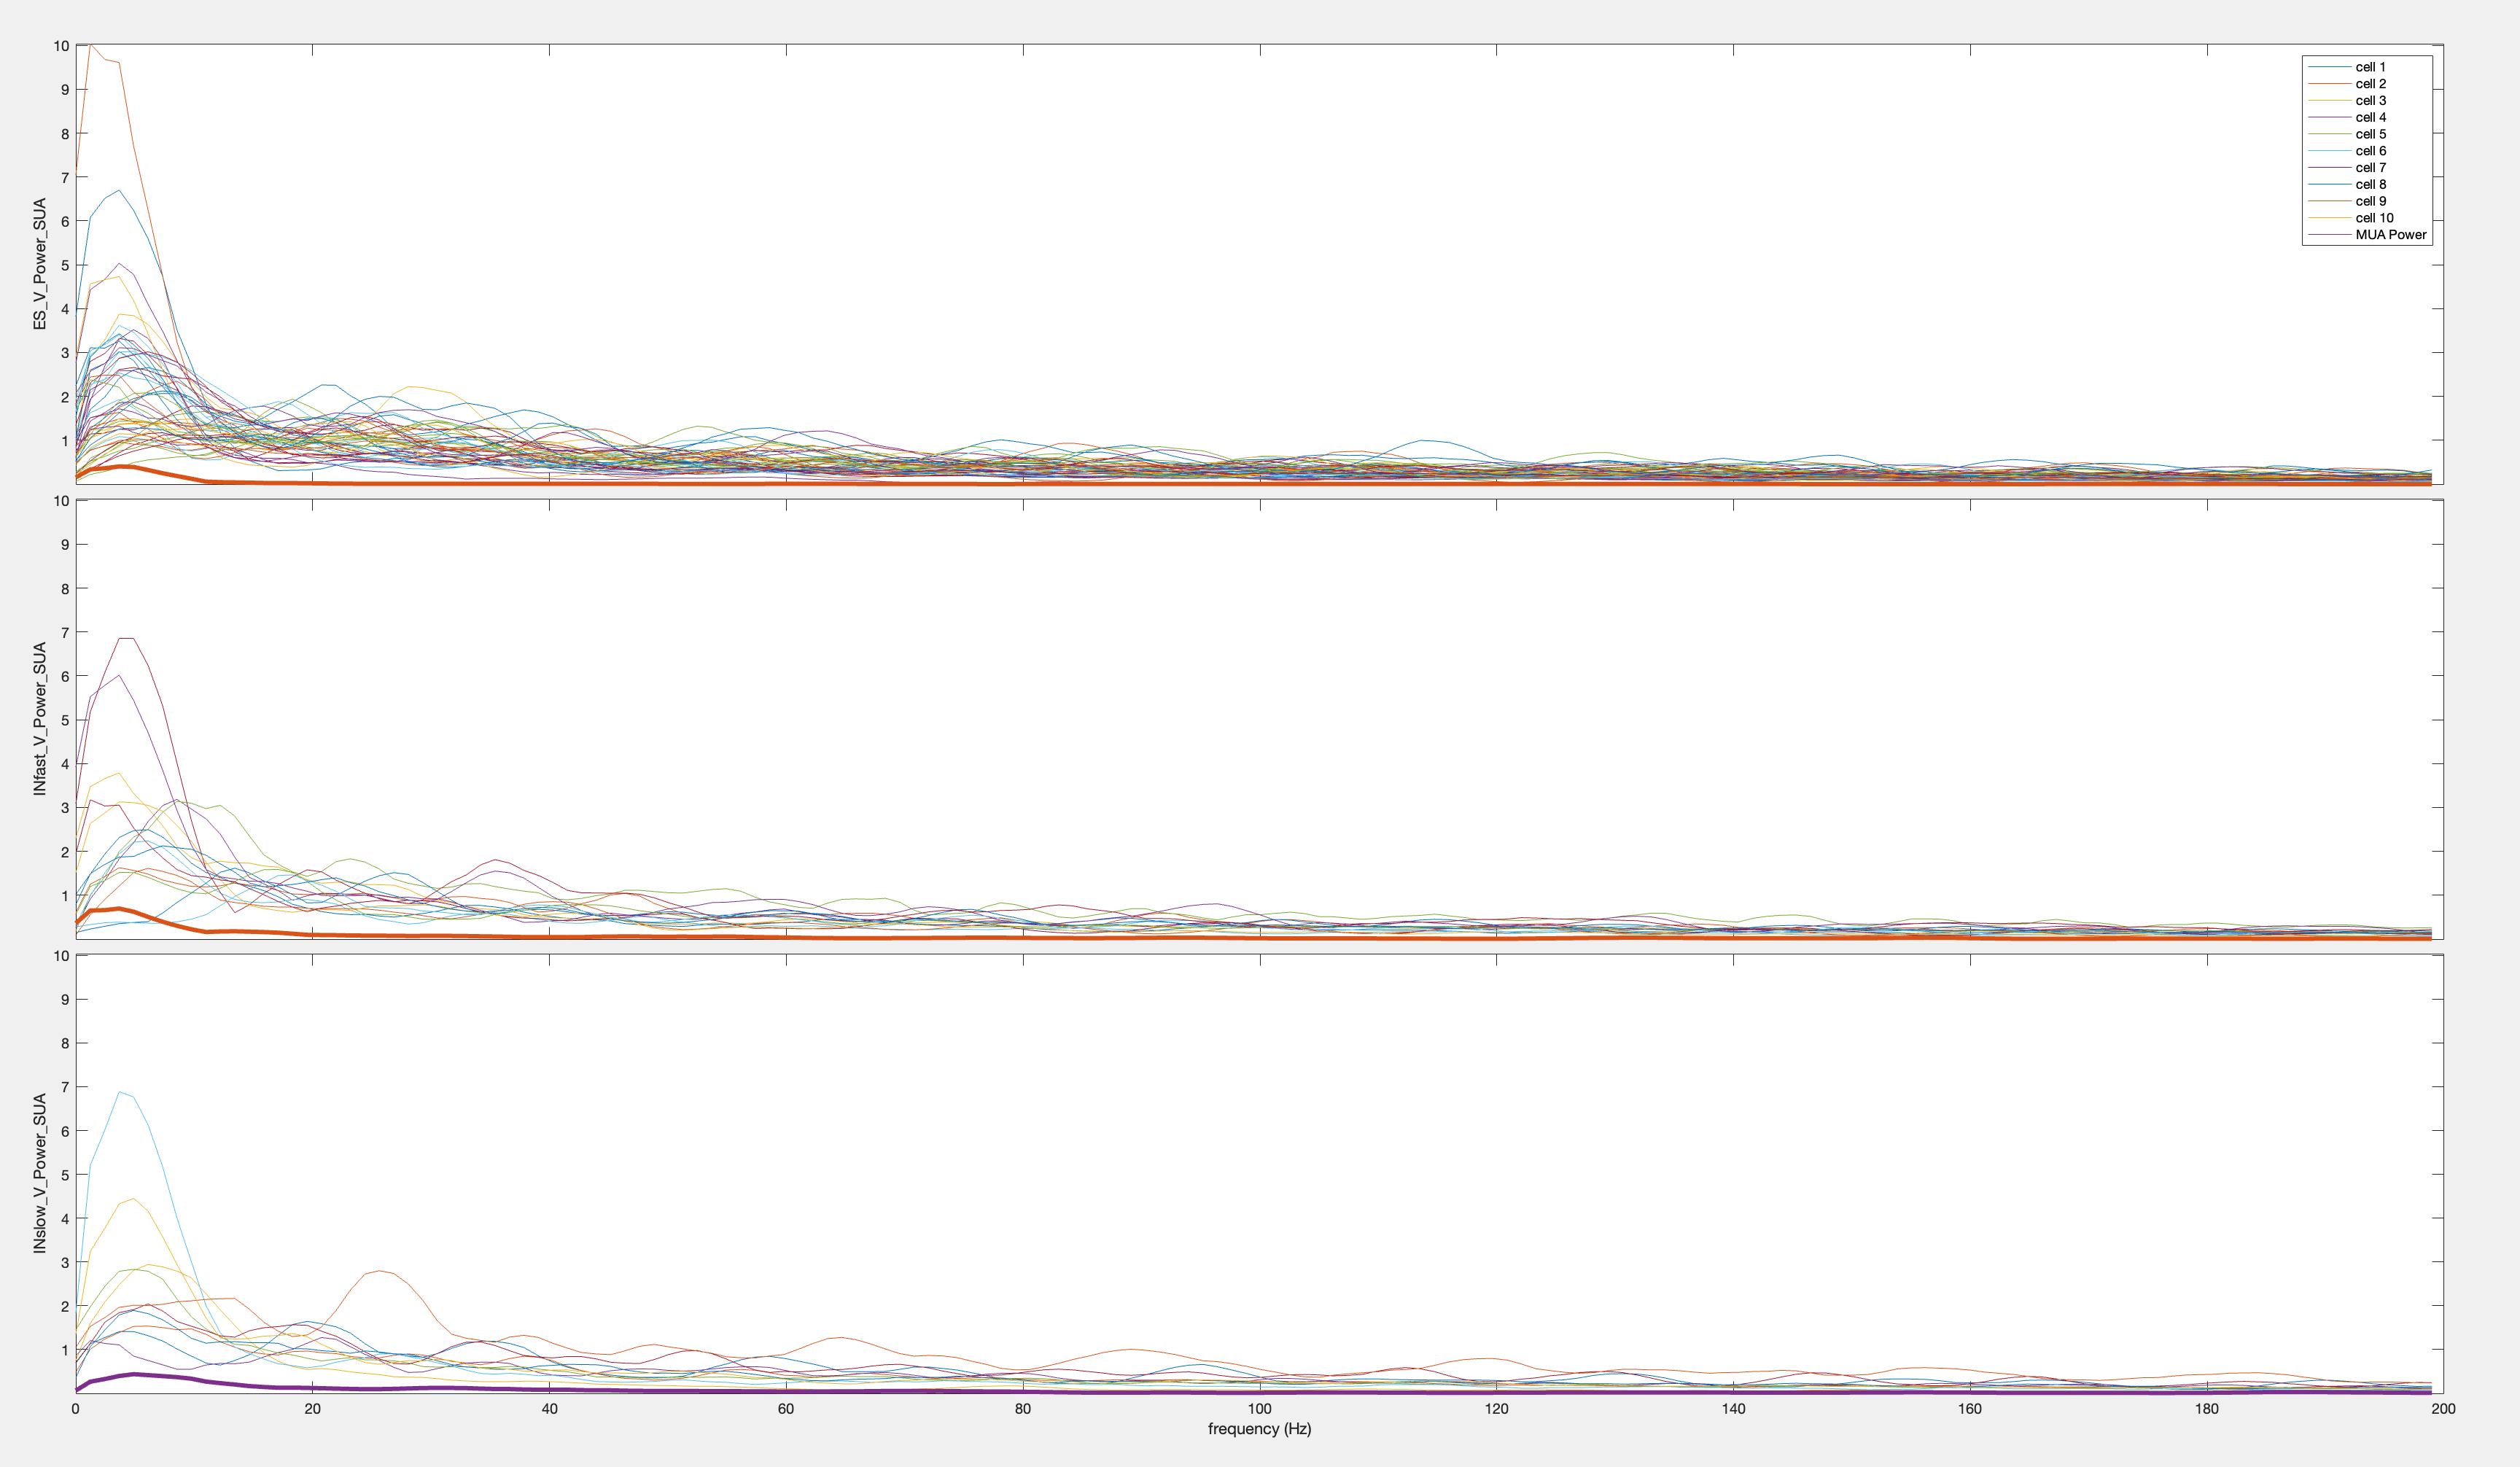

dsPlot(data, 'plot_type','power');

## 2. DynaLearn object initialization

dl = DynaLearn(s, study_dir, 'mex', 'PINO', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/dlModels/PINO1
Creating data directory: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/dlModels/PINO1/data
Creating results directory: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/dlModels/PINO1/results
saving study file: /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/dlModels/PINO1/studyinfo.mat

PREPARING SOLVER:
Creating solver directory /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/dlModels/PINO1/solve/sim1
Changing directory to /Users/hamednejat/Works/Research/Computational/DynaSim/DynaSim/dlModels/PINO1/solve/sim1
Saving params.mat
Creating solver file: /Users/hamednejat

dl.dlSave();


->Model saved in "dlModels/PINO1/dlFile.mat".


- Loader; if the model already exists.

id = 1; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/PINO" + num2str(id)));

DL object loaded from dlModels/PINO1 
Params.mat file loaded from dlModels/PINO1 
--------
--->Constructing graph ... Done.

Reinitialized.


x = load("mstB2poGLO.mat").x;

y = zeros(size(x, 1), size(x, 2), 5000);
for i = 1:size(x, 1)

    for j = 1:size(x, 2)

        w = squeeze(x(i, j, 1:5000));
        fx = dlSpectrum(w, 1000);
        y(i, j, :) = fx;

    end

end

targetVspectrum = mean(squeeze(mean(y, 1)), 1);
targetVspectrum = targetVspectrum(11:1000); % 1-100Hz
targetVspectrum = targetVspectrum - min(targetVspectrum) + 1e-9;

RunDuration = 2000;
dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = {['ES', '_V'], 1:75, [1 RunDuration], 'afr'};
dlTargetParameters = {[{'KLD', 1, targetVspectrum, 1e+5, 1, 100}; {'MSE', 1, 5, 1e-1, 0, 0}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-2; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.2;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = "iAMPA_netcon";

dlTrainOptions('dlCheckpointCoefficient') = 1.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> iAMPA_netcon
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
-->No variables were manually restricted in the fitting restrict list.
--->No dynasim variables are restricted by default.
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, defau

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/PINO1/Optimal 
---->Optimal [Parallel]


Condition1



	->Single trial running: 
Updating parameters of dlModels/PINO1/solve > 
Done.

	-->Simulation outputs:     {[26.3318]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


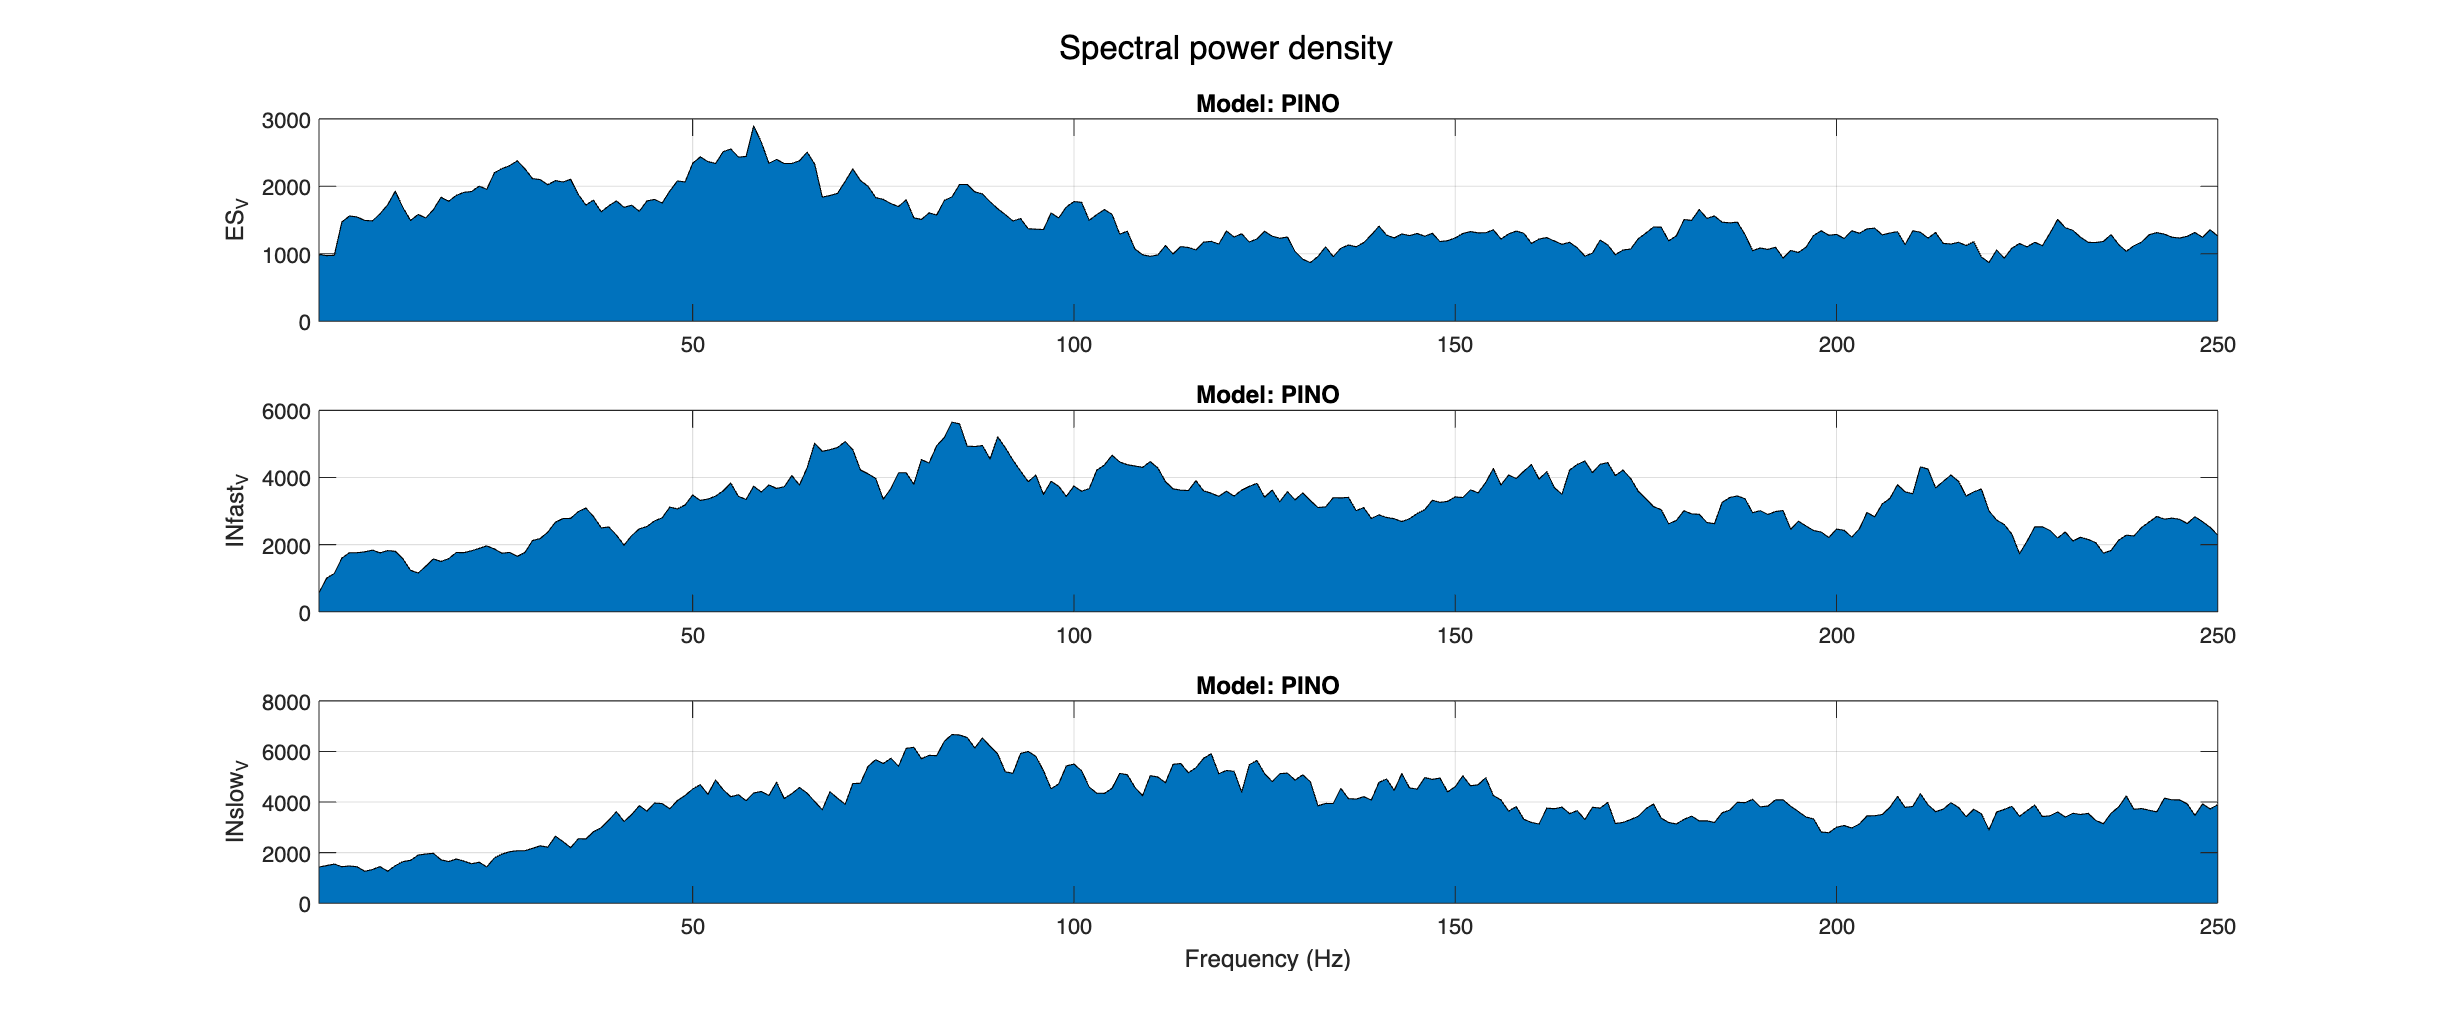

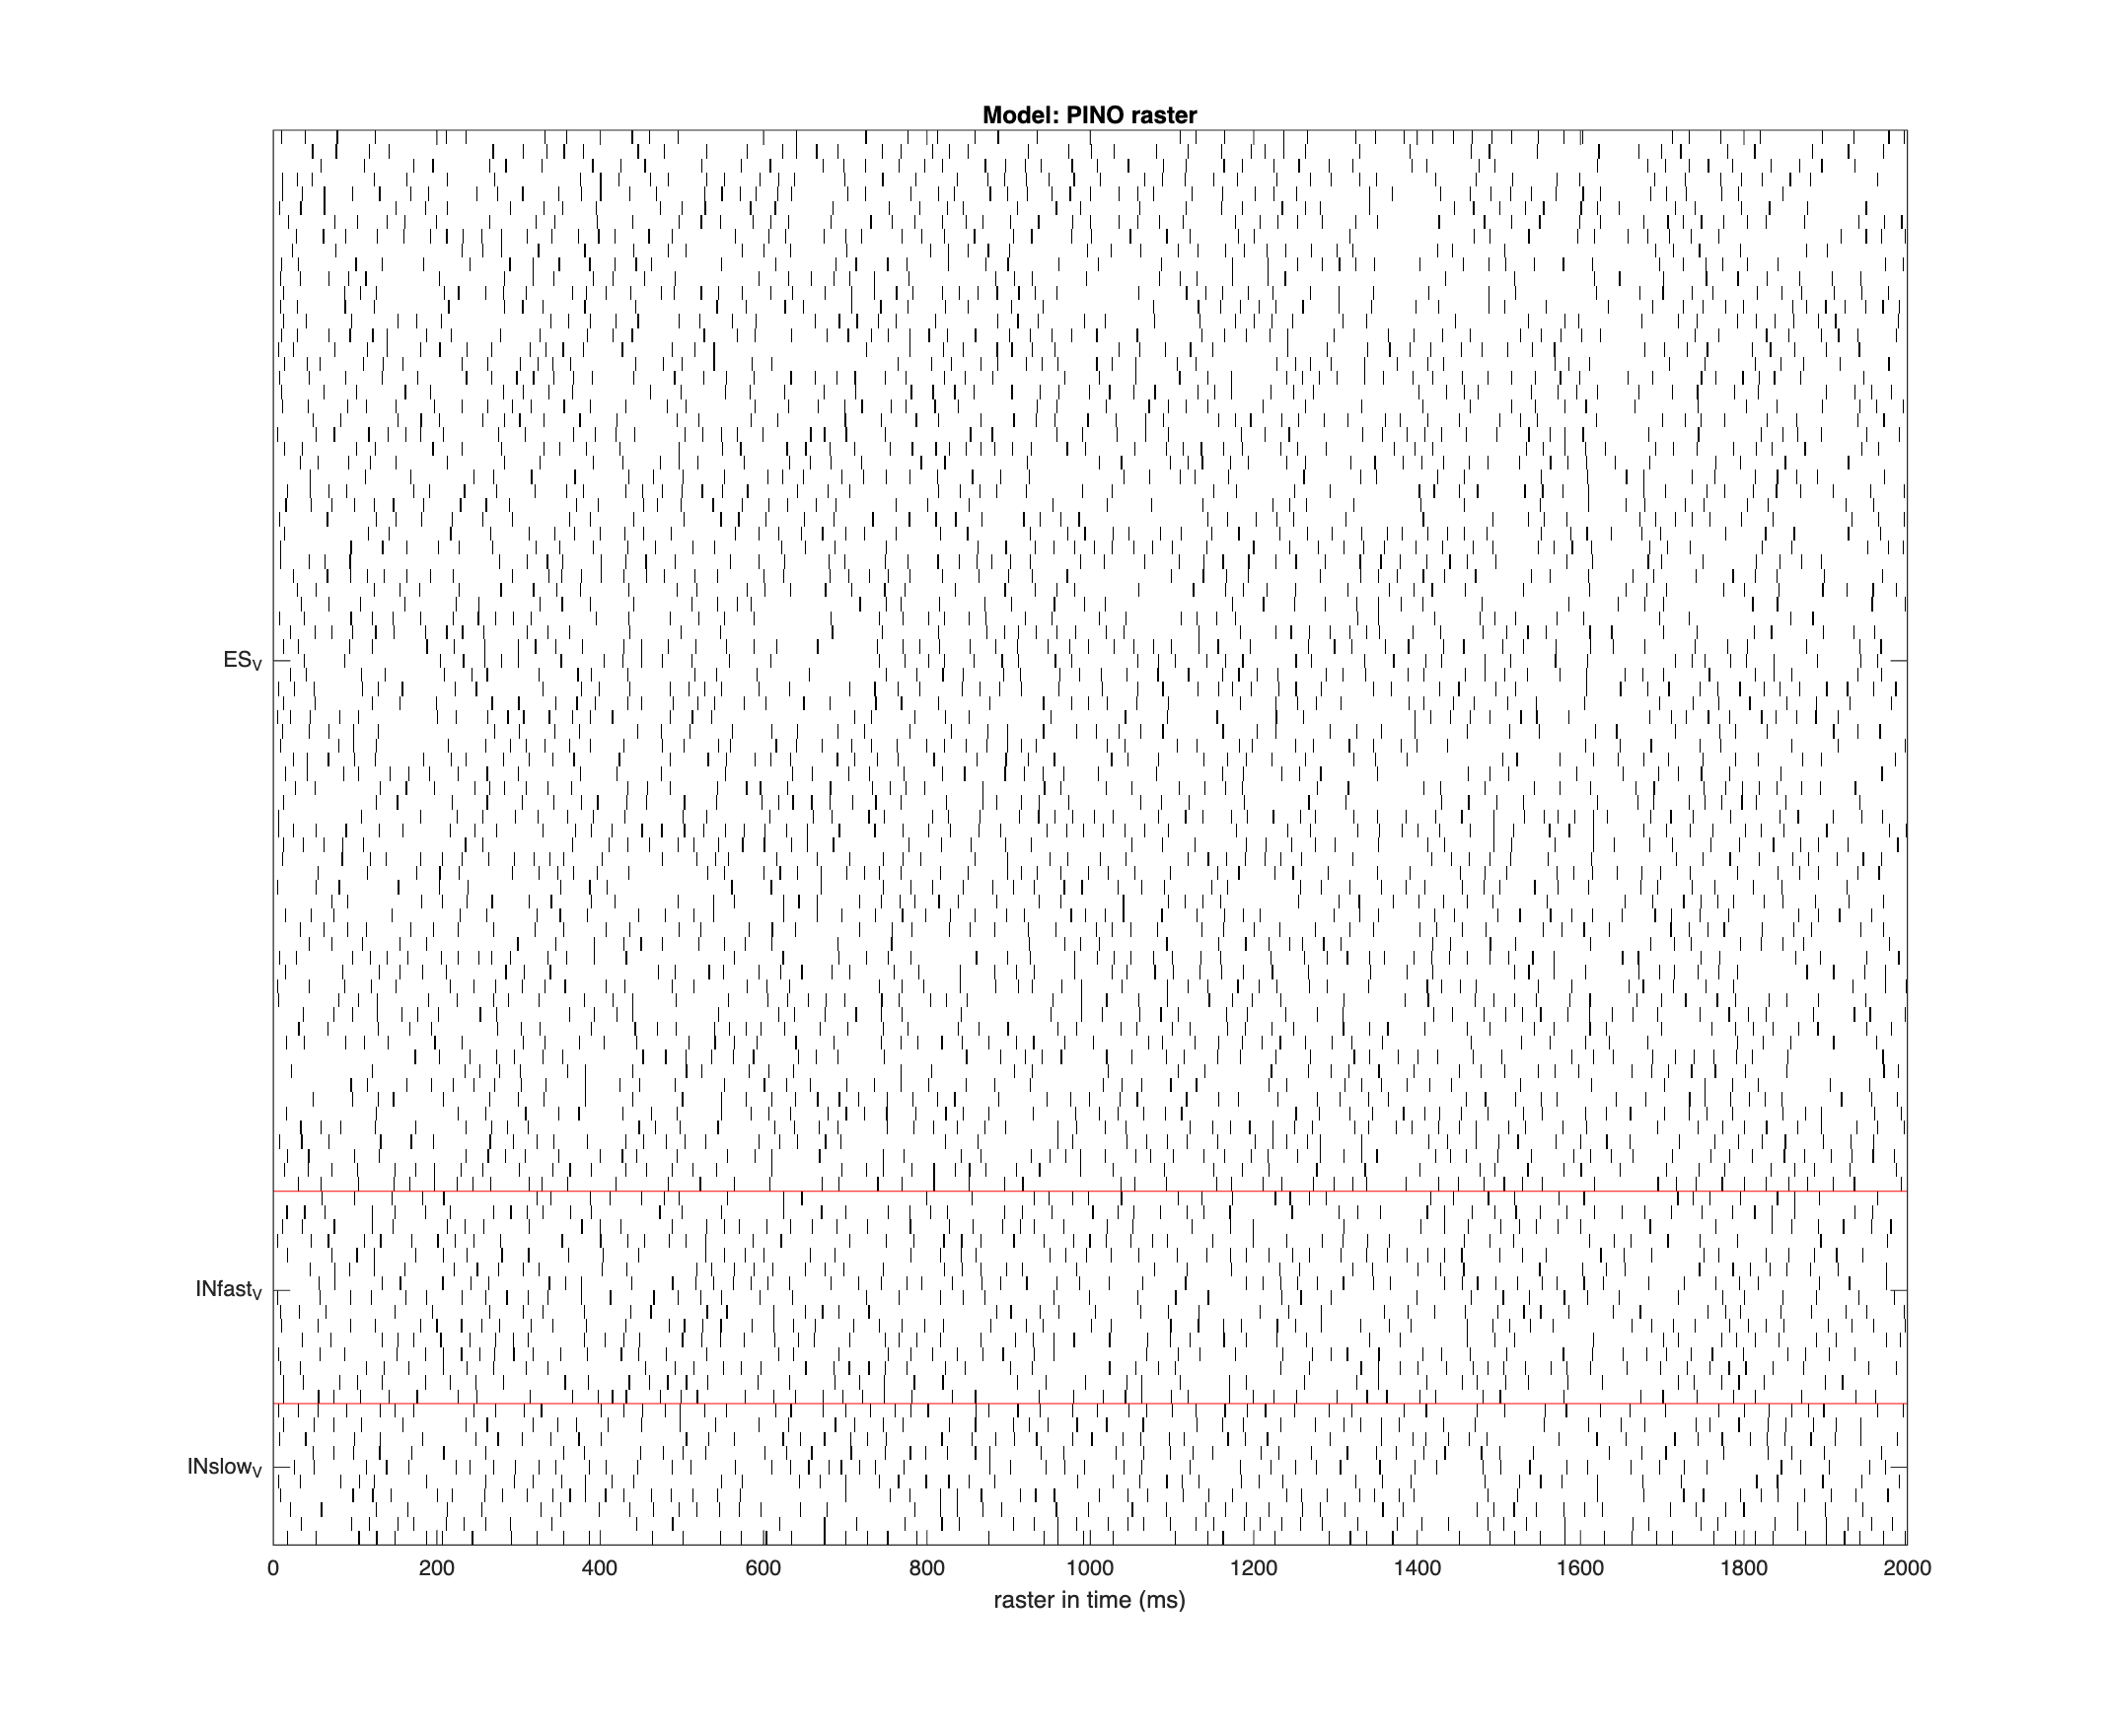

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

## End